# Statistiques licences

d = datetime();
d.Format = "dd/MM/yyyy";
fprintf(1, "Rapport créé le %s\n", d);

Rapport créé le 19/02/2025


files = stats.io.ReadCSV.fromFolder("data");
files = sort(files);
read(files)

## Etat

### Total

fprintf("Nombre de licenciés = %d\n", height(files(end).Data));

Nombre de licenciés = 15916


### Répartition par discipline

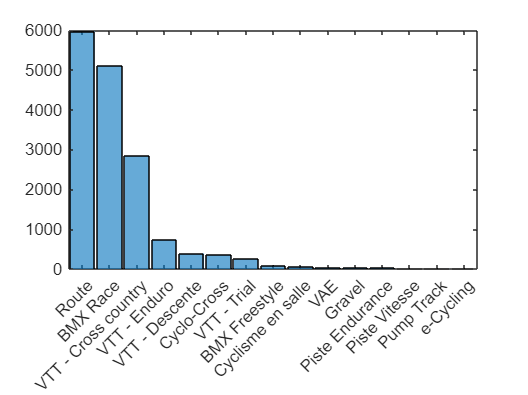

[g,T] = findgroups(files(end).Data(:,"Discipline"));
T.Nombre = splitapply(@length, files(end).Data.Discipline, g);
[~,idx] = sort(T.Nombre,"descend");
T = T(idx,:);
histogram(reordercats(files(end).Data.Discipline,idx))

disp(T)

        Discipline         Count
    ___________________    _____

    Route                  5970 
    BMX Race               5109 
    VTT - Cross country    2847 
    VTT - Enduro            742 
    VTT - Descente          397 
    Cyclo-Cross             355 
    VTT - Trial             253 
    BMX Freestyle            76 
    Cyclisme en salle        52 
    VAE                      43 
    Gravel                   30 
    Piste Endurance          28 
    Piste Vitesse             5 
    Pump Track                5 
    e-Cycling                 4 



## Evolution